control

testid=4;
dir1=['single_section/day2 single section/Test ',num2str(testid),'/'];

f=dir([dir1,'Dapi*.tif']);
flist={f.name};
t=Tiff([dir1,flist{1}]);
Dapi_control=read(t);
% Dapi_control=sum(Dapi_control,3);

% Dapi_control(Dapi_control<5*mean(Dapi_control(:)))=0;
% regmax = imregionalmax(Dapi_control);
% [points_x,points_y]=find(regmax>0);
% figure;imshow(uint8(Dapi_control));
% hold on
% plot(points_y,points_x,'r.')
% 
% p=FastPeakFind(Dapi_control,5*mean(Dapi_control(:)));
% imagesc(Dapi_control); hold on
% plot(p(1:2:end),p(2:2:end),'r+')

results=readtable([dir1,'Results2.csv']);
points_y=results.X;
points_x=results.Y;

points_loc=[points_y,points_x];
NUMBER=size(points_x,1);
SAMPLE=100;
% [sizebyk_cpu,sizebyk_dis_cpu] = DPC_1(points_loc,NUMBER,SAMPLE);

for i=1:NUMBER
    if i>size(points_loc,1)
        break;
    end
    point=points_loc(i,:);
    [sizebyk,sizebyk_dis] = knnsearch(points_loc,point,'K',SAMPLE);
    flag=1;
    for j=2:SAMPLE
        if sizebyk_dis(j)>35
            break;
        end
        
    end
    if j>2
        points_loc(sizebyk(2:j-1),:)=[];
    end
end

points_loc=points_loc+1;

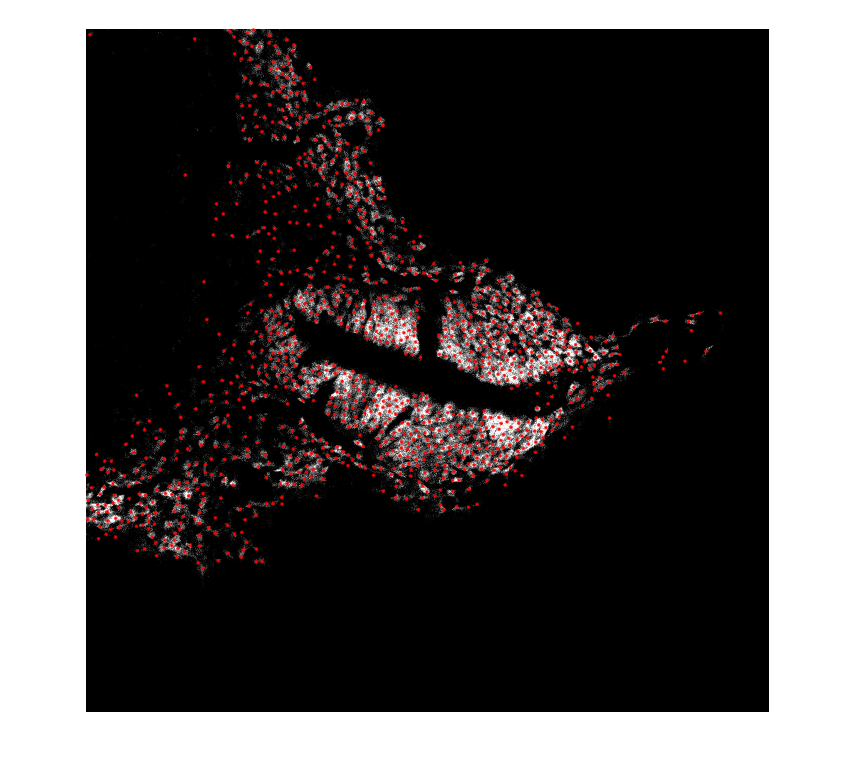

figure;imshow(2*Dapi_control)
hold on
plot(points_loc(:,1),points_loc(:,2),'.','Color','r','markersize',6.5)

Dapi_cell_num=size(points_loc,1);
% saveas(gcf,[dir1,num2str(Dapi_cell_num),'_',flist{1}])

cell in hucd

f=dir([dir1,'HuCD*.tif']);
flist={f.name};
t=Tiff([dir1,flist{1}]);
hucd_control=read(t);
hucd_control=sum(hucd_control,3);

BW2 = imfill(imbinarize(hucd_control),'holes');

hucd_list=[];
for i=1:size(points_loc,1)
    if BW2(points_loc(i,2),points_loc(i,1))>0
        hucd_list(end+1,1:2)=points_loc(i,:);
    end
end

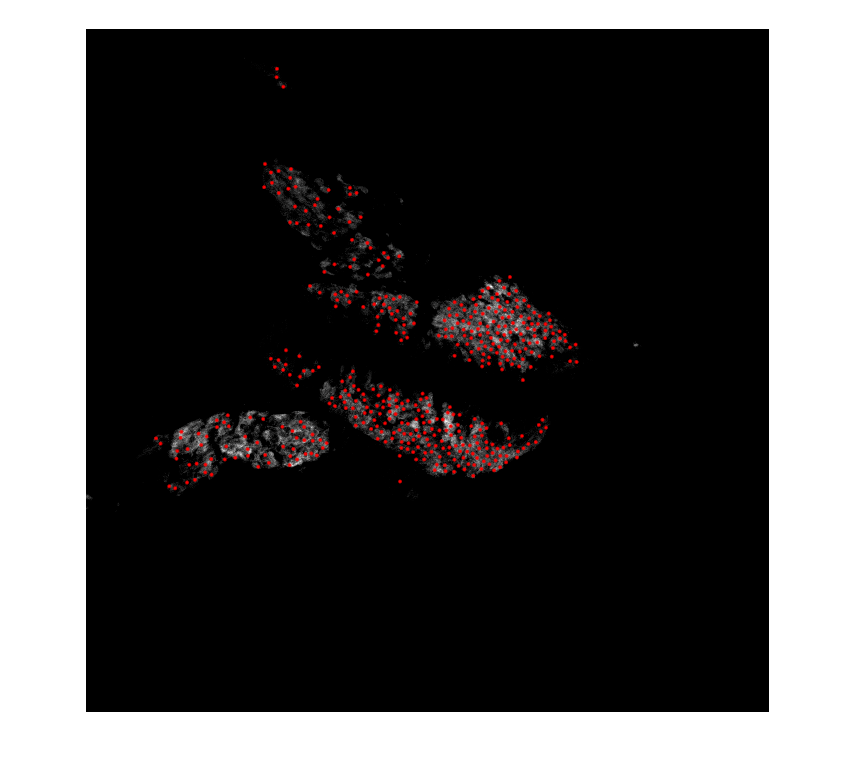

f=dir([dir1,'HuCD*.tif']);
flist={f.name};
t=Tiff([dir1,flist{1}]);
hucd_control=read(t);

figure;imshow(hucd_control*2)
hold on
plot(hucd_list(:,1),hucd_list(:,2),'.','Color','r','markersize',7.5)

% saveas(gcf,[dir1,'HuCD_cell.tif'])

Dapi_cell_num=size(hucd_list,1);
% saveas(gcf,[dir1,num2str(Dapi_cell_num),'_',flist{1}])

% span=max(points_loc(:,1))-min(points_loc(:,1));
% min_location=min(points_loc(:,1));
% 
% width=span/50;
% curve_hucd=[];
% 
% for i=1:50
%     left_loc=min_location+(i-1)*width;
%     right_loc=min_location+(i)*width;
%     p=find(hucd_list(:,1)>=left_loc & hucd_list(:,1)<right_loc);
%     curve_hucd(i)=length(p);
% end

% figure;plot(curve_hucd,'r');

cell in sox

f=dir([dir1,'Sox*.tif']);
flist={f.name};
t=Tiff([dir1,flist{1}]);
hucd_control=read(t);
hucd_control=sum(hucd_control,3);

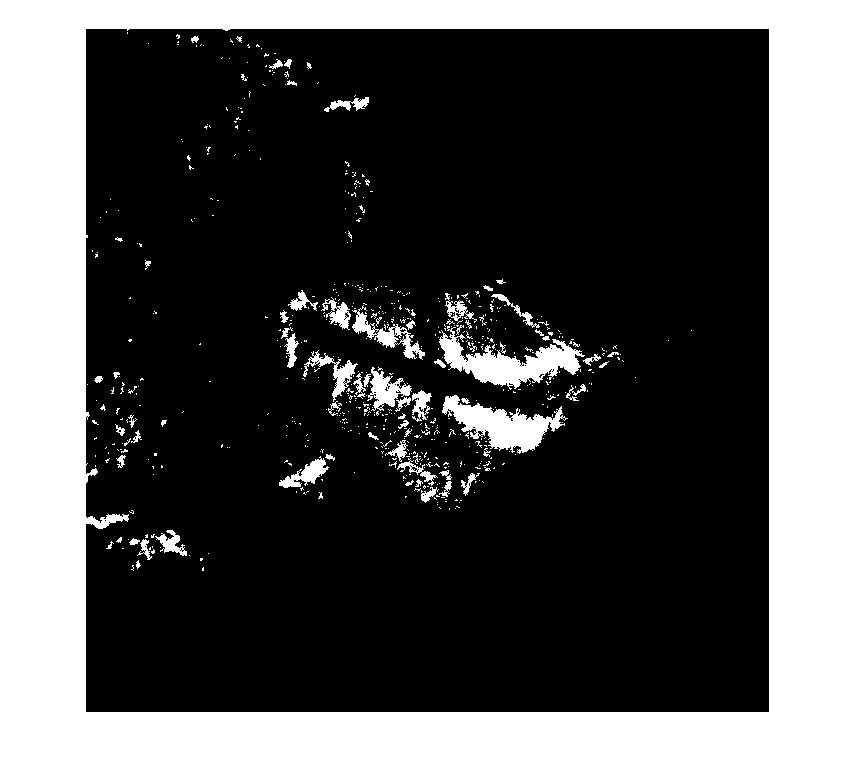

hucd_control=imgaussfilt(hucd_control);
BW2 = imfill(imbinarize(hucd_control),'holes');
BW2=bwareaopen(BW2,35);
figure;
imshow(BW2)

hucd_list=[];
for i=1:size(points_loc,1)
    if BW2(points_loc(i,2),points_loc(i,1))>0
        hucd_list(end+1,1:2)=points_loc(i,:);
    end
end

figure;imshow(hucd_control*2)
hold on
if ~isempty(hucd_list)
    plot(hucd_list(:,1),hucd_list(:,2),'.','Color','r','markersize',8)
end
% saveas(gcf,[dir1,'HuCD_cell.tif'])

Dapi_cell_num=size(hucd_list,1);
saveas(gcf,[dir1,num2str(Dapi_cell_num),'_',flist{1}])

% span=max(points_loc(:,1))-min(points_loc(:,1));
% min_location=min(points_loc(:,1));
% 
% width=span/50;
% curve_sox2=[];
% 
% for i=1:50
%     left_loc=min_location+(i-1)*width;
%     right_loc=min_location+(i)*width;
%     p=find(hucd_list(:,1)>=left_loc & hucd_list(:,1)<right_loc);
%     curve_sox2(i)=length(p);
% end

% figure;plot(curve_sox2,'r');